close all
clear all
clc
plot_counter=1;
Question_mark='Q23_J3 ';

num=[1 +1/0.8];
den=conv([1 -0.15],[1 -0.2]);
d=5;
d0=4;

A=den;B=num;
n=length(A)-1;

[alpha,beta]=d_step_maker(A,B,d);

T_s=0.3;
tfinal=100;
freq=5;
variance=0.01;
C=0;
[uc,t,Status,tfinal,Noix]=Datagen(1,T_s,tfinal,freq,variance,C);
Titlework=[Question_mark,Status];
uc(1:40,1)=ones(40,1);

N=numel(t);
u=zeros(1,N);
y=zeros(1,N);
u_hat=zeros(1,N);
var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);
P = ([1 -.7 -.2]);
R = conv([1 -.8 ],poly(1));
R_prime = R(2:end);
P_prime = P(2:end);
Normerror=0;
Error=0;
lambda=+1;
for i=d+n+d0:N-d
    y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d0:-1:i-length(B)+1-d0)';
    u(i)=((beta(1)*(uc(i+d)-alpha*y(i:-1:i-n+1)'-beta(2:end)*u(i-1:-1:i-length(beta(2:end)))'+ lambda*P_prime*u_hat(i-1:-1:i-length(P_prime))' - lambda*R_prime*u(i-1:-1:i-length(R_prime))' ) )/ (beta(1)^2+lambda));
    u_hat(i)=-P(2:end)*u_hat(i-1:-1:i-length(P_prime))'+R*u(i:-1:i-length(R)+1)';
    var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
    var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;
    Error=(y(i)-uc(i))^2+Error;
    Normerror=norm(Error,2)+Normerror;
end

% figure(1)
% rlocus(tf(1,conv(P,[B,0])+lambda/(beta(2:end).*conv(A,R)),1))

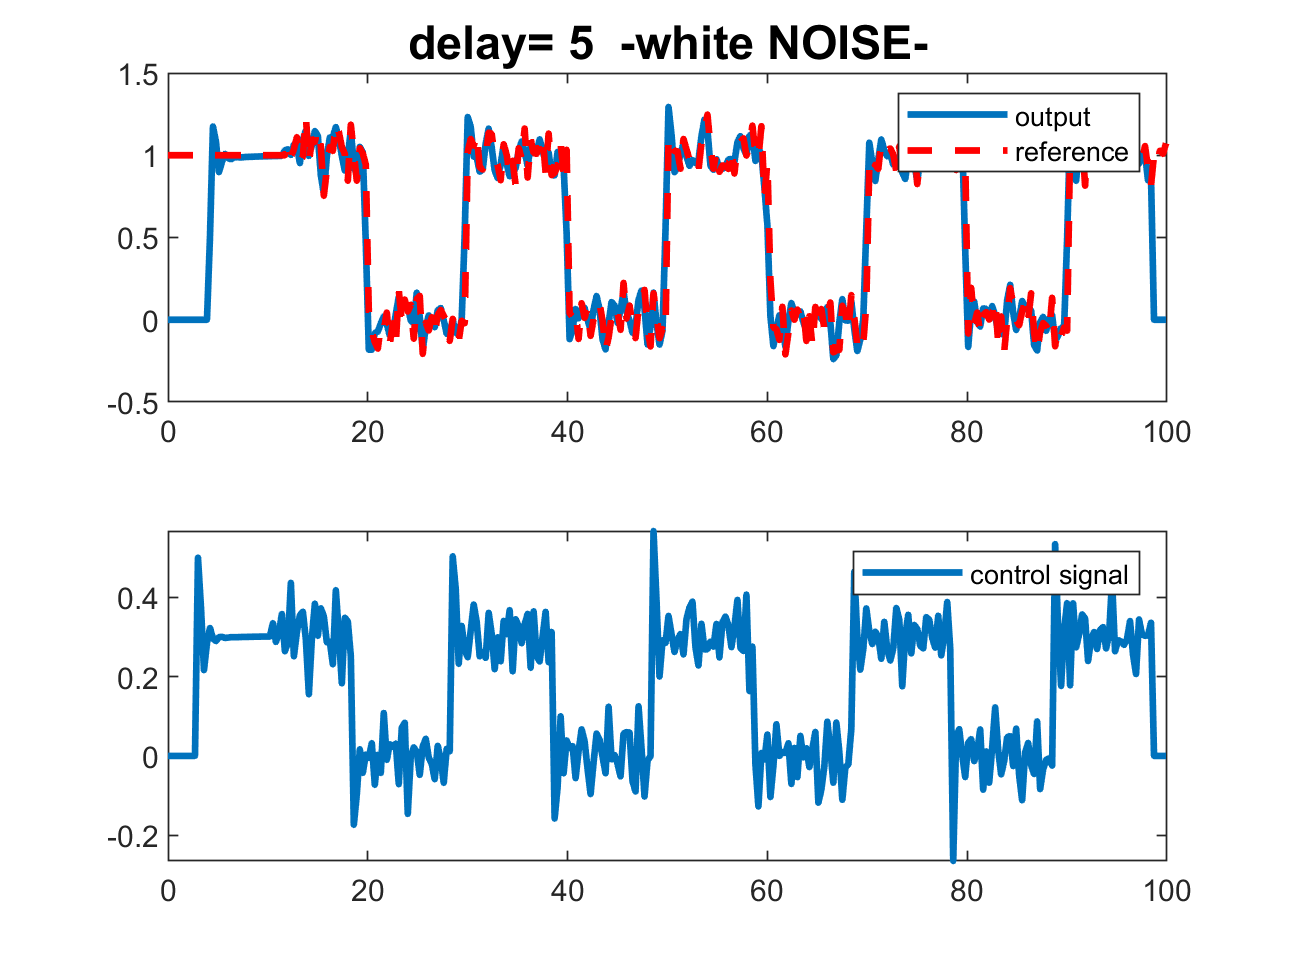

figure(2);
subplot(2,1,1);
    plot(t,y,t,uc','--r','linewidth',2);
    title(['delay= ',num2str(d) '  ', Status],'fontsize',14)
    legend('output','reference');

subplot(212);
    plot(t,u,'linewidth',2);
%     title('control signal','Color','b','fontsize',14);
    legend('control signal');

print(gcf,[Titlework , ' d=' num2str(d) ' Result.png'],'-dpng','-r400');

plot_counter=plot_counter+1;

disp(['mean of u=',num2str(mean_u(end-d)),'   mean of y=',num2str(mean_y(end-d))])

mean of u=0.16869   mean of y=0.54277


disp(['Error of u=',num2str(Error),'   NormError of y=',num2str(Normerror)])      

Error of u=7.9648   NormError of y=1909.5644
